## Problem 1.

다음과 같이 1차 ARX model을 고려하자

$y(t) - 0.9y(t-1) = b_0 u(t) + \nu(t)$, $b_0 =\left\lbrace \begin{array}{ll}
1\ldotp 5 & t\le \frac{N}{2}\\
0\ldotp 5 & t>\frac{N}{2}
\end{array}\right.$

이때 N = 400이고, noise $\nu$는 $N(0, 0.1^2)$을 따른다고 하자.

clc; close all; clear all;

### a)

$t = [0, N/2]$ 시간 동안 batch data에 대해 1차 ARX 모델을 추정하기 위한 LSM solution $\left(\hat{a} ,\hat{b} \right)$를 구하라

***sol)***

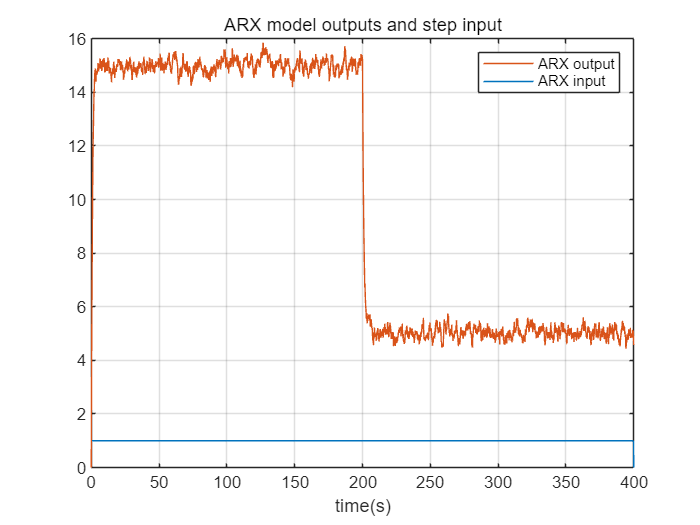

rng(0);
% ARX_model
timestep_T = 0.1;
N = 400;
time = linspace(0, N, N/timestep_T + 1);
output_data = zeros([length(time), 1]);
input_data = zeros([length(time), 1]);

output_y = 0;       % y(t)
prev_output_y = 0;  % y(t-1)
input_u = 1;        % Unit step input
noise_nu = 0.1;     % Gaussian noise with zero mean, 0.1 std

for t = 1 : length(time)
    if (t + 1 > length(time))
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    output_data(t+1) = output_y;
    input_data(t) = input_u;
    prev_output_y = output_y;
end

Input = plot(time, input_data);
hold on; grid on;
Output = plot(time, output_data);
legend([Output, Input], {"ARX output", "ARX input"});
xlabel("time(s)"); title("ARX model outputs and step input");
hold off;

위의 loop를 토대로 y(0) = 0이라는 initial condition 가정을 세우고, LSM에 사용할 수 있는 output y의 data를 `y(2:end, :)`까지 얻을 수 있다. 위 코드는 unit step input에 대해서 ARX 모델이 noise $N(0, 0.1^2)$을 포함한 output 데이터를 획득하기 위해서 작성됐다. 이를 바탕으로 LSM solution $\left(\hat{a} ,\hat{b} \right)$을 도출할 수 있다.


$$\begin{array}{l}
Y={\left\lbrack \begin{array}{cccc}
y\left(2\right) & y\left(3\right) & \cdots \; & y\left(n\right)
\end{array}\right\rbrack }^T \\
Y^- ={\left\lbrack \begin{array}{cccc}
y\left(1\right) & y\left(2\right) & \cdots \; & y\left(n-1\right)
\end{array}\right\rbrack }^T \\
U={\left\lbrack \begin{array}{cccc}
u\left(2\right) & u\left(3\right) & \cdots \; & u\left(n\right)
\end{array}\right\rbrack }^T \\
\hat{\Theta} ={\left\lbrack \begin{array}{cc}
\hat{a}  & \hat{b} 
\end{array}\right\rbrack }^T \\
\hat{\Theta} ={\left({\left\lbrack \begin{array}{cc}
Y^-  & U
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{cc}
Y^-  & U
\end{array}\right\rbrack \right)}^{-1} {\left\lbrack \begin{array}{cc}
Y^-  & U
\end{array}\right\rbrack }^T Y\;
\end{array}$$


Y = output_data(2:end, :);
Y_ = output_data(1:end-1, :);
U = input_data(2:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.9993
    0.0079


$t \leq N/2$의 데이터만으로 LSM을 진행했을 때 $\hat{b}_0$와 $\hat{a}_0$의 추정이 모두 원래의 값과 비슷한 것을 확인할 수 있다.

Y = output_data(2:(length(output_data)-1)/2, :);
Y_ = output_data(1:(length(output_data)-1)/2-1, :);
U = input_data(2:(length(output_data)-1)/2, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.8961
    1.5578


마찬가지로 $t > N/2$의 데이터만으로 LSM을 진행했을 때 $\hat{b}_0$와 $\hat{a}_0$의 추정이 모두 원래의 값과 비슷한 것을 확인할 수 있다.

Y = output_data((length(output_data)-1)/2+1:end, :);
Y_ = output_data((length(output_data)-1)/2:end-1, :);
U = input_data((length(output_data)-1)/2+1:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.9176
    0.4141


위처럼 중간에 $b_0$가 변하는 상황에선** LTI(Linear time invariance) 가정이 어긋나**기에 LSM을 적용했을 때 $\hat{b}_0$는 아래의 두 추정보다 상대적으로 더 오차가 큰 모습을 확인할 수 있고, $\hat{a}_0$는 그 중간에도 미치지 못한 모습을 확인할 수 있다.

Sinusoidal input에 대해서도 LSM을 진행해 보았다.

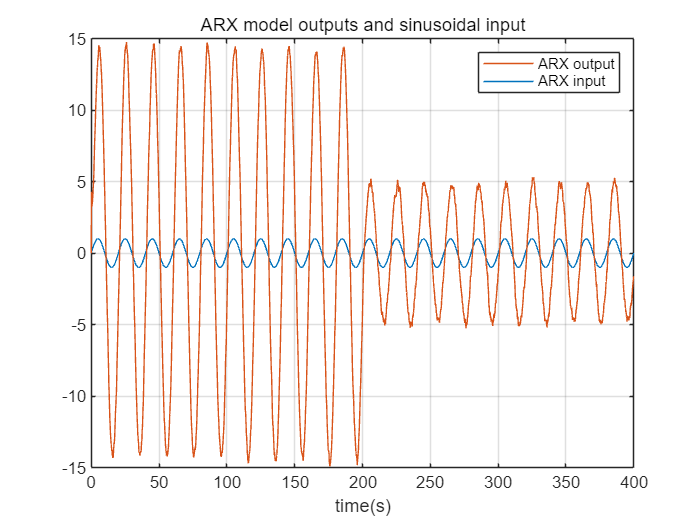

cycle_time = 20;
output_sinusoidal_data = zeros([length(time), 1]);
input_sinusoidal_u = sin(time.*(2*pi)./cycle_time)';
for t = 1 : length(time)
    if (t + 1 > length(time))
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_sinusoidal_u(t + 1) + noise_nu*randn;
    % sinusoidal input에 대한 ARX model의 output data계산
    output_sinusoidal_data(t+1) = output_y;
    prev_output_y = output_y;
end

Input = plot(time, input_sinusoidal_u);
hold on; grid on;
Output = plot(time, output_sinusoidal_data);
legend([Output, Input], {"ARX output", "ARX input"});
xlabel("time(s)"); title("ARX model outputs and sinusoidal input");
hold off;

Y = output_sinusoidal_data(2:end, :);
Y_ = output_sinusoidal_data(1:end-1, :);
U = input_sinusoidal_u(2:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.9726
    0.3363


$t \leq N/2$**의 데이터만으로 LSM을 진행**

Y = output_sinusoidal_data(2:(length(output_data)-1)/2, :);
Y_ = output_sinusoidal_data(1:(length(output_data)-1)/2-1, :);
U = input_sinusoidal_u(2:(length(output_data)-1)/2, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.8991
    1.5135


$t > N/2$**의 데이터만으로 LSM을 진행**

Y = output_sinusoidal_data((length(output_data)-1)/2+1:end, :);
Y_ = output_sinusoidal_data((length(output_data)-1)/2:end-1, :);
U = input_sinusoidal_u((length(output_data)-1)/2+1:end, :);
Phi = [Y_, U];
LSM_sol = (Phi'*Phi)\Phi'*Y

LSM_sol =     0.8986
    0.5128


Sinusoidal input을 이용해 LSM을 진행했을 때도 마찬가지로 LTI 가정이 깨져 $t \leq N/2$, $t > N/2$ 각각의 데이터를 사용했을 때보다 한꺼번에 추정했을 때의 parameter 추정이 $0.5$ 근처에만 간 모습을 확인할 수 있다.

## b)

Initial parameter와 초기 covariance를 다음과 같이 설정하였다고 하였을 때, $\rho =\left\lbrack \begin{array}{ccc}
0\ldotp 1, & 1, & 10
\end{array}\right\rbrack$에 따른 recursive estimator를 설계하여라. $t=[0, N/2]$에 대한 $y$의 시간반응을 그래프로 나타내고, a) 결과와 비교하여라. 또한, $\rho$에 따른 그래프의 경향성을 분석하여라.


$$\hat{\theta \;} \left(0\right)=0,\;\;\;P\left(0\right)=\rho \;\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


***sol)***

LSM의 batch 형태는 $\hat{\theta}(t) = \left(\sum_{k=1}^t H(k)^TH(k)\right)^{-1}\left(\sum_{k=1}^t H(k)^Ty(k)\right)$와 같다.

$P(t) = \left(\sum_{k=1}^t H(k)^TH(k)\right)^{-1}$라고 정의했을 때, $\hat{\theta}(t) = P(t)\left(\sum_{k=1}^t H(k)^Ty(k)\right)= P(t)X(t)$, 


$$X(t) = P(t)^{-1}\hat{\theta}(t)$$



$$X(t-1) = P(t-1)^{-1}\hat{\theta}(t-1)$$


이다. 위 식들을 현 iteration과 이전 iteration까지의 $\sum$으로 분리하면

$\hat{\theta}(t) = P(t)\left(\sum_{k=1}^t H(k)^Ty(k)\right) = P(t)\left(\sum_{k=1}^{t-1} H(k)^Ty(k) + H(t)^Ty(t)\right) = P(t)\left(P^{-1}(t-1)\hat{\theta}(t-1) + H(t)^Ty(t)\right)$이다.


$$A = P^{-1}(t-1)$$



$$B = H(t)^T$$



$$C = I$$



$$D = H(t)$$


위 조건 하에서 Sherman Morrison Woodbury formula의 lamma를 사용해 현 iteration의 $\hat{\theta}(t)$을 이전 iteration의 $\hat{\theta}(t-1)$을 이용해 구할 수 있다.


$$\hat{\theta}(t) = P(t)\left[\sum_{k=1}^{t-1}H(k)^Ty(k) + H(t)^Ty(t)\right]$$


      
$$=  P(t)\left[P^{-1}(t-1)\hat{\theta}(t-1) + H(t)^Ty(t)\right]$$


      
$$= P(t)\left[\left(P^{-1}(t) - H(t)^TH(t)\right)\hat{\theta}(t-1) + H(t)^Ty(t)\right]$$


      
$$= \hat{\theta}(t-1) + P(t)H(t)^T\left[y(t) - H(t)\hat{\theta}(t-1)\right]$$


초기 파라미터의 covariance matrix의 추정을 $P(0)$로 설정하므로 $P(0) = \rho I$이다.

위의 $P(t)$는 아래의 식에 따라 갱신된다.


$$P(t) = P(t-1) - P(t-1)H(t)^T\left[ I + H(t)P(t-1)H(t) \right]^{-1}H(t)P(t-1)$$



$$K(t) = P(t)H(t)^T = P(t-1)H(t)^T\left[I + H(t)P(t-1)H(t)\right]^{-1}$$



$$\hat{\theta}(t) = \hat{\theta}(t-1) + K(t)e(t)$$


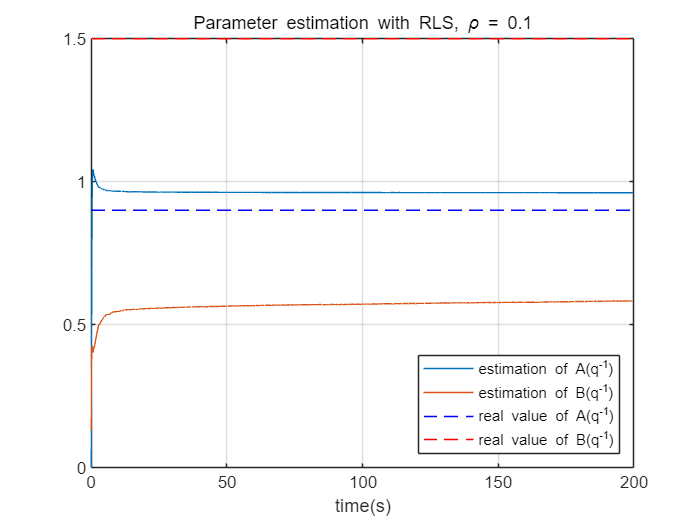

output_y = 0;       % y(t)
prev_output_y = 0;  % y(t-1)
input_u = 1;        % Unit step input
noise_nu = 0.1;     % Gaussian noise with zero mean, 0.1 std

rho_nums = [0.1, 1, 10];
rho_P = rho_nums(1).*eye(2);
prev_rho_P = rho_P;
hat_theta = zeros([2, 1]);
hat_theta_prev = hat_theta;
hat_theta_data = [];
recursive_H = [];
for t = 1 : length(time)
    if (t + 1 > length(time)/2)
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    recursive_H = [prev_output_y, input_u];
    error = output_y - recursive_H*hat_theta;
    rho_P = prev_rho_P - prev_rho_P*recursive_H'*((1 + recursive_H*prev_rho_P*recursive_H')\recursive_H)*prev_rho_P;
    K = rho_P*recursive_H';
    hat_theta = hat_theta_prev + K*error;
    prev_rho_P = rho_P;
    hat_theta_prev = hat_theta;
    hat_theta_data = [hat_theta_data, hat_theta];
    prev_output_y = output_y;
end

a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), 1.5*ones([length(hat_theta_data), 1]), 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'southeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \rho = 0.1");
hold off;

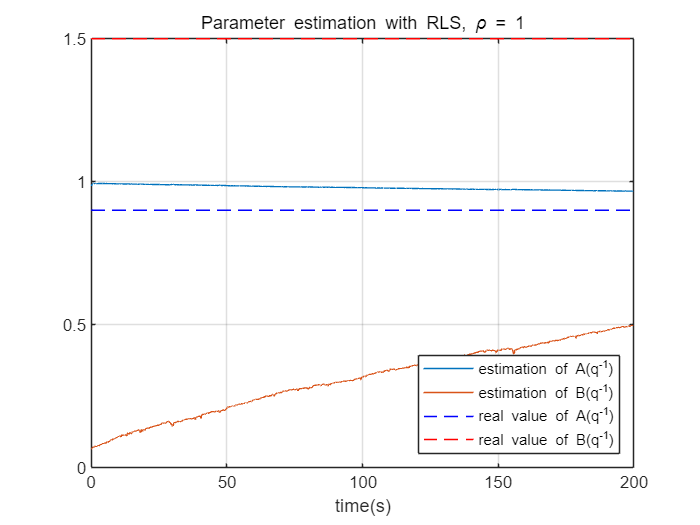

rho_P = rho_nums(2).*eye(2);
prev_rho_P = rho_P;
hat_theta = zeros([2, 1]);
hat_theta_prev = hat_theta;
hat_theta_data = [];
recursive_H = [];
for t = 1 : length(time)
    if (t + 1 > length(time)/2)
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    recursive_H = [prev_output_y, input_u];
    error = output_y - recursive_H*hat_theta;
    rho_P = prev_rho_P - prev_rho_P*recursive_H'*((1 + recursive_H*prev_rho_P*recursive_H')\recursive_H)*prev_rho_P;
    K = rho_P*recursive_H';
    hat_theta = hat_theta_prev + K*error;
    prev_rho_P = rho_P;
    hat_theta_prev = hat_theta;
    hat_theta_data = [hat_theta_data, hat_theta];
    prev_output_y = output_y;
end

a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), 1.5*ones([length(hat_theta_data), 1]), 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'southeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \rho = 1");
hold off;

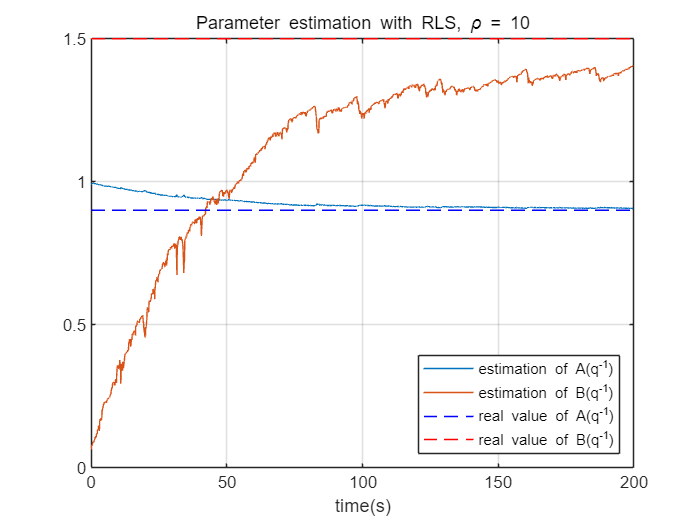

rho_P = rho_nums(3).*eye(2);
prev_rho_P = rho_P;
hat_theta = zeros([2, 1]);
hat_theta_prev = hat_theta;
hat_theta_data = [];
recursive_H = [];
for t = 1 : length(time)
    if (t + 1 > length(time)/2)
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    recursive_H = [prev_output_y, input_u];
    error = output_y - recursive_H*hat_theta;
    rho_P = prev_rho_P - prev_rho_P*recursive_H'*((1 + recursive_H*prev_rho_P*recursive_H')\recursive_H)*prev_rho_P;
    K = rho_P*recursive_H';
    hat_theta = hat_theta_prev + K*error;
    prev_rho_P = rho_P;
    hat_theta_prev = hat_theta;
    hat_theta_data = [hat_theta_data, hat_theta];
    prev_output_y = output_y;
end

a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), 1.5*ones([length(hat_theta_data), 1]), 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'southeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \rho = 10");
hold off;

$P(0)$가 커짐에 따라 $A(q^{-1})$, $B(q^{-1})$ 각각의 1차 계수, 0차 계수의 추정이 기존의 맞는 값에 더 가까워지는 것을 확인할 수 있다. 이는 $\hat{\theta}(t)$의 갱신 방법을 통해 확인할 수 있는데, $P(t)$가 클수록 output $y(t)$가 $\hat{\theta}(t)$ 갱신에 적용되는 비율이 높아지고 $P(t)$가 작을수록 이전 iteration에서 추정한 $\hat{\theta}(t-1)$의 비중이 $\hat{\theta}(t)$ 갱신시 더 커지는 것을 확인할 수 있다.

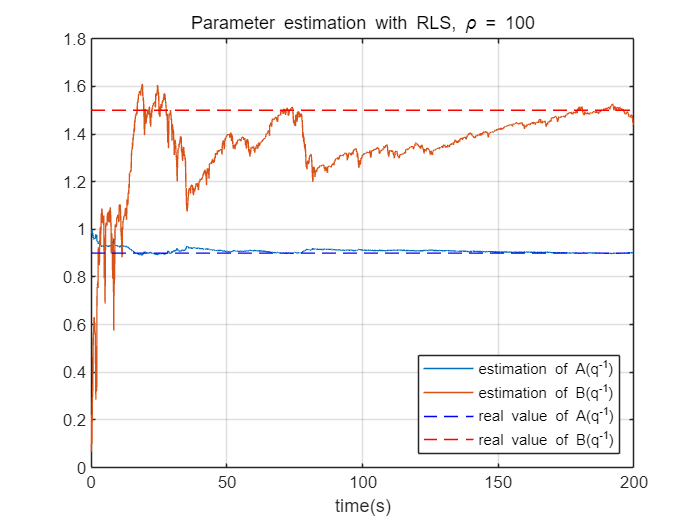

rho_P = 100.*eye(2);
prev_rho_P = rho_P;
hat_theta = zeros([2, 1]);
hat_theta_prev = hat_theta;
hat_theta_data = [];
recursive_H = [];
for t = 1 : length(time)
    if (t + 1 > length(time)/2)
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    recursive_H = [prev_output_y, input_u];
    error = output_y - recursive_H*hat_theta;
    rho_P = prev_rho_P - prev_rho_P*recursive_H'*((1 + recursive_H*prev_rho_P*recursive_H')\recursive_H)*prev_rho_P;
    K = rho_P*recursive_H';
    hat_theta = hat_theta_prev + K*error;
    prev_rho_P = rho_P;
    hat_theta_prev = hat_theta;
    hat_theta_data = [hat_theta_data, hat_theta];
    prev_output_y = output_y;
end

a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), 1.5*ones([length(hat_theta_data), 1]), 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'southeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \rho = 100");
hold off;

 이를 극단적으로 보여주기 위해 $P(0)$의 $\rho$를 100으로 설정해 표를 뽑아본다면 위와 같이 $\rho$가 10일 때보다 참 값 1.5에 더 가까워지는 것을 확인할 수 있다. 하지만, noise에 취약해져 $\rho$가 10일 때보다 transient response에서 진동하는 모습을 확인할 수 있다. 즉, covariance matrix를 결정하는 $\rho$가 커짐에 따라 $\hat{\theta}(t)$의 갱신 과정에서 관측한 data의 비중이 높아지는 대신, noise에 취약해져 $\hat{\theta}(t)$가 수렴하는 과정에서 진동이 많이 발생할 수 있고, $\rho$가 작아지면 $\hat{\theta}(t)$의 갱신 과정에서 이전 추정 parameter의 비중이 높아지는 대신, 빠른 반응, 적응이 어려움을 확인할 수 있다. ***a) sol)***과 비교했을 때, $N/2$ batch data에 대해서 값은 least square가 실제 값과 더 유사했지만, 갱신되는 데이터에 따라 계산량에서 RLS(recursive least square) method가 더 좋은 성능을 보이는 것을 확인할 수 있다.

## c)

Forgetting factor $\lambda$를 도입하여 recursive least square estimator를 설계하여라. $\rho =\left\lbrack 0,N\right\rbrack \;$에 대한 y의 시간반응을 그래프로 나타내고, $\lambda$에 따른 그래프의 경향성을 분석하여라

***sol)***

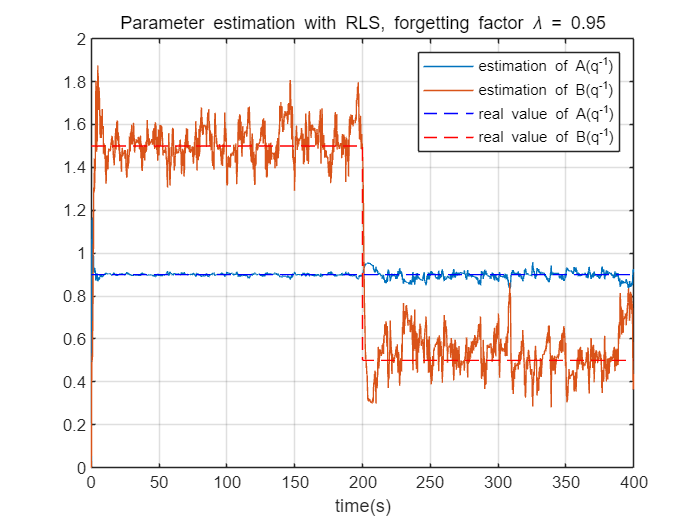

lambda = [0.95, 0.995, 1];
hat_theta_data = prob_c(time, lambda(1));
a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, forgetting factor \lambda = 0.95");
hold off;

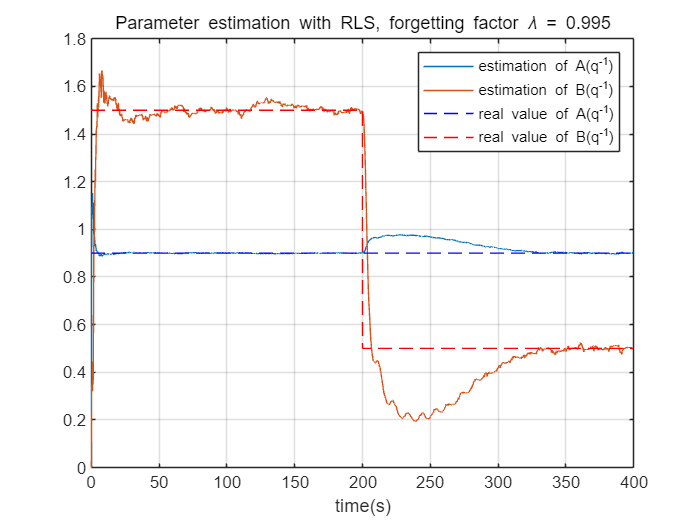

hat_theta_data = prob_c(time, lambda(2));

a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, forgetting factor \lambda = 0.995");
hold off;

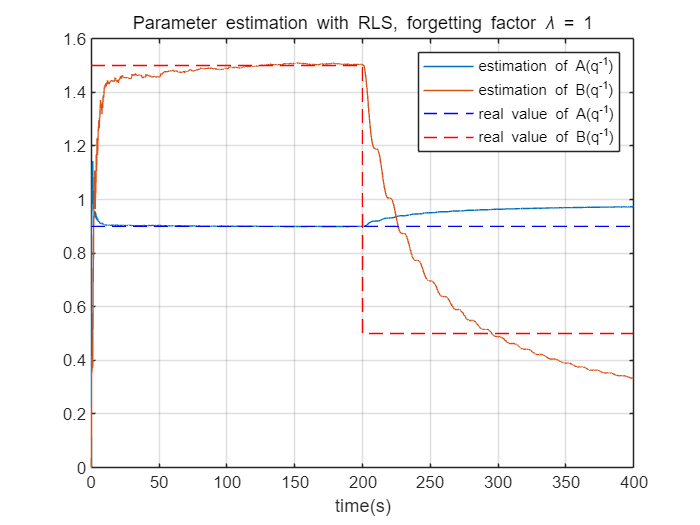

hat_theta_data = prob_c(time, lambda(3));

a1 = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on;
b1 = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
real_b1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
legend([a1, b1, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, forgetting factor \lambda = 1");
hold off;

Step input으로 반응성을 살필 시 $B(q^{-1})$의 parameter 추정이 판단하기 어려운 형태로 출력되어 주기 20초, magnitude 1의 sinusoidal input을 이용해 forgetting factor를 적용한 RLS의 결과를 나타내었다. 각각 lambda가 $0.95, 0.995, 1$일 때의 그래프들인데, forgetting factor가 클수록 추정 parameter가 느리게 수렴하는 것을 확인할 수 있고, forgetting factor가 작을수록 반응성이 빨라지지만, 외부 noise에 취약해지는 모습을 확인할 수 있다. 

## Functions

- Problem 1-c) function

function hat_theta_data = prob_c(time, lambda)
    output_y = 0;       % y(t)
    prev_output_y = 0;  % y(t-1)
    noise_nu = 0.1;     % Gaussian noise with zero mean, 0.1 std
    cycle_time = 20;
    input_sinusoidal_u = sin(time.*(2*pi)./cycle_time)';
    rho_P = 10.*eye(2);
    prev_rho_P = rho_P;
    hat_theta = zeros([2, 1]);
    hat_theta_prev = hat_theta;
    hat_theta_data = [];
    recursive_H = [];
    for t = 1 : length(time)
        if (t + 1 > length(time))
            break;
        end
        if t <= (length(time)-1)/2
            b_0 = 1.5;
        else
            b_0 = 0.5;
        end
        output_y = 0.9*prev_output_y + b_0*input_sinusoidal_u(t) + noise_nu*randn;
        % step input에 대한 ARX model의 output data계산
        recursive_H = [prev_output_y, input_sinusoidal_u(t)];
        error = output_y - recursive_H*hat_theta_prev;
        rho_P = (prev_rho_P - prev_rho_P*recursive_H'*((lambda + recursive_H*prev_rho_P*recursive_H')\recursive_H)*prev_rho_P)./lambda;
        K = rho_P*recursive_H';
        hat_theta = hat_theta_prev + K*error;
        prev_rho_P = rho_P;
        hat_theta_prev = hat_theta;
        hat_theta_data = [hat_theta_data, hat_theta];
        prev_output_y = output_y;
    end
end